Notlarım:

- Elimde hazır olan augmentation datası ile yapıldı.

- Hızlı olsun diye fiziksel filtreler uygulanmamış dataya uyguladım. (40-50 data).

- İlk olarak normal distribution fit edildi.

- İkinci olarak kernel density estimation (kde) kullandım. bandwidth'i otomatik bıraktım.

- Normal distribution'da confidence level var ama kde'de öyle bişey bulamadım.

- kde'de bir probability belirleyip ona denk gelen datayı çekebilirim ?.

- kde'nin bandwidth ayarlanabilir.

- kde'nin fit etmesi için normal distribution verdim ama başka distributionlar da verilebilir. örnek: datası az olan yerde uniform?

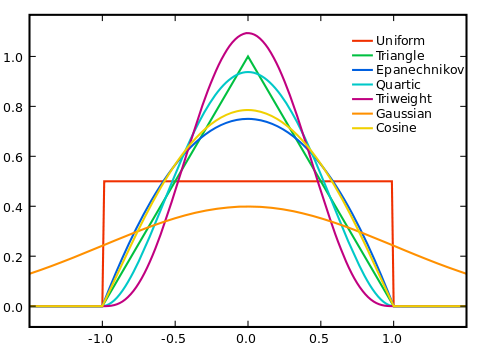

[KDE](https://www.mathworks.com/help/stats/kernel-distribution.html)

[KDE parameters](https://www.mathworks.com/help/stats/ksdensity.html#namevaluepairarguments) (log gibi data transformation var).

[Matlab fit edilebilen distributionlar](https://www.mathworks.com/help/stats/fitdist.html#btu538h-distname)

clearvars
close all

aug_data = load('output_data\aug_output.mat').aug_data;
segments = load('input_data\osm.mat').osm;
markers = load('input_data\markers.mat').markers;
% adding distance from origin column to aug_out
[~,b] = ismember(aug_data.segment_id,segments.segment_id);
aug_data.distance_from_start = segments.distance_from_start(b);

corridor_length = 1e-3 * max(sum(segments(segments.dir==2,:).calc_length) , sum(segments(segments.dir==1,:).calc_length));

aug_data.Properties.VariableNames{2} = 'time';


aux_segments = unique(aug_data.segment_id);
filter = NaN(size(aug_data,1),1);
for i=1:1:length(aux_segments)
    filter(aug_data.segment_id == aux_segments(i)) = isoutlier(aug_data(aug_data.segment_id == aux_segments(i),:).speed,'quartiles');
end
aug_data.filter = ~logical(filter);
size(aug_data,1);
sum(filter);

c = unique([aug_data.segment_id,aug_data.dir],'rows');
aux_segments = c(c(:,2) == 1,1);

% sinyalsiz segmentler NaN + last segment
delete_segments = horzcat([115:144],316);
for i=1:1:length(delete_segments)
    aux_segments = aux_segments(~(aux_segments == delete_segments(i)));
end

time_1 = datetime({'2019-11-18 08:00:00'});
time_2 = datetime({'2019-11-18 10:00:00'});
aux_time = time_1:minutes(15):time_2;

n_time = length(aux_time) - 1;

pd_cell = cell(length(aux_segments),n_time);
kernel_cell = cell(length(aux_segments),n_time);

n_data = NaN(length(aux_segments),n_time);
aug_data = sortrows(aug_data,["segment_id","time"]);

for i=1:1:length(aux_segments)
    for j=1:1:n_time
        index = aug_data.segment_id == aux_segments(i) & aug_data.time >= aux_time(j) & aug_data.time < aux_time(j+1);
        n_data(i,j) = sum(index);
        pd_cell{i,j} = fitdist(aug_data.speed(index),'Normal');
        kernel_cell{i,j} = fitdist(aug_data.speed(index),'Kernel');
    end
end

con_min = NaN(length(aux_segments),n_time);
con_max = NaN(length(aux_segments),n_time);
for i=1:1:length(aux_segments)
    for j=1:1:n_time
        data = paramci(pd_cell{i,j},'Alpha',0.05,'Parameter','mu');
        con_min(i,j) = data(1);
        con_max(i,j) = data(2);
    end
end

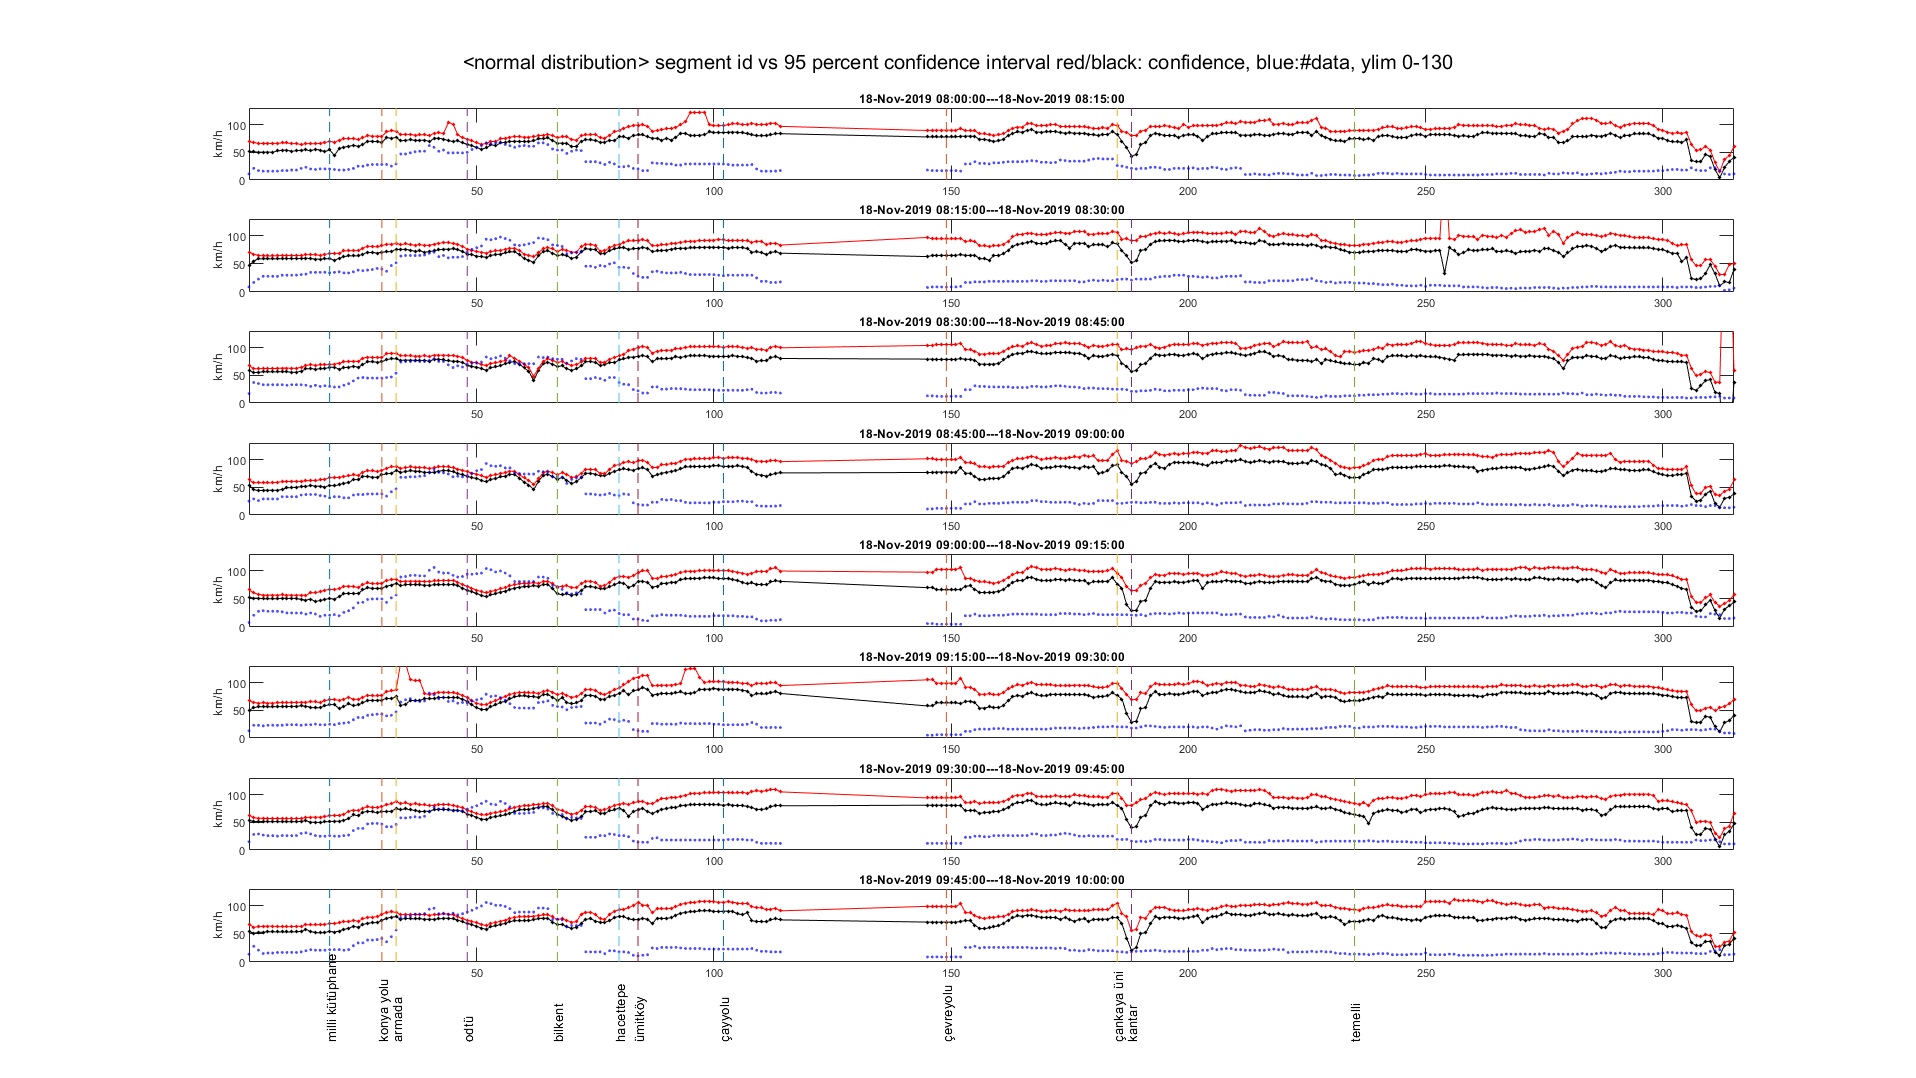

dir_chosen = 1;
h=figure();
for i=1:1:length(aux_time)-1
    ax1 = subplot(length(aux_time)-1,1,i);
    plot(ax1,aux_segments,con_min(:,i),'-*k',"MarkerSize",2);
    hold(ax1,'on');
    plot(ax1,aux_segments,con_max(:,i),'-*r',"MarkerSize",2);
    hold(ax1,'on');
    scatter(ax1,aux_segments,n_data(:,i),5,'blue','filled','MarkerEdgeAlpha',0.7,"MarkerFaceAlpha",0.7);
    xlim(ax1,[min(aux_segments) max(aux_segments)])
    ylabel('km/h')
    ylim([0 130]);
    yLimits = get(ax1,'YLim');
    title([datestr(aux_time(i)), '---', datestr(aux_time(i+1))])
    line(ax1,[markers.segment_id(markers.dir == dir_chosen),markers.segment_id(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
end
text(ax1, double(markers.segment_id(markers.dir == dir_chosen)), -1.1*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
set(h,'Units','normalized','Position',[0 0 1 1]);
sgtitle('<normal distribution> segment id vs 95 percent confidence interval red/black: confidence, blue:#data, ylim 0-130')

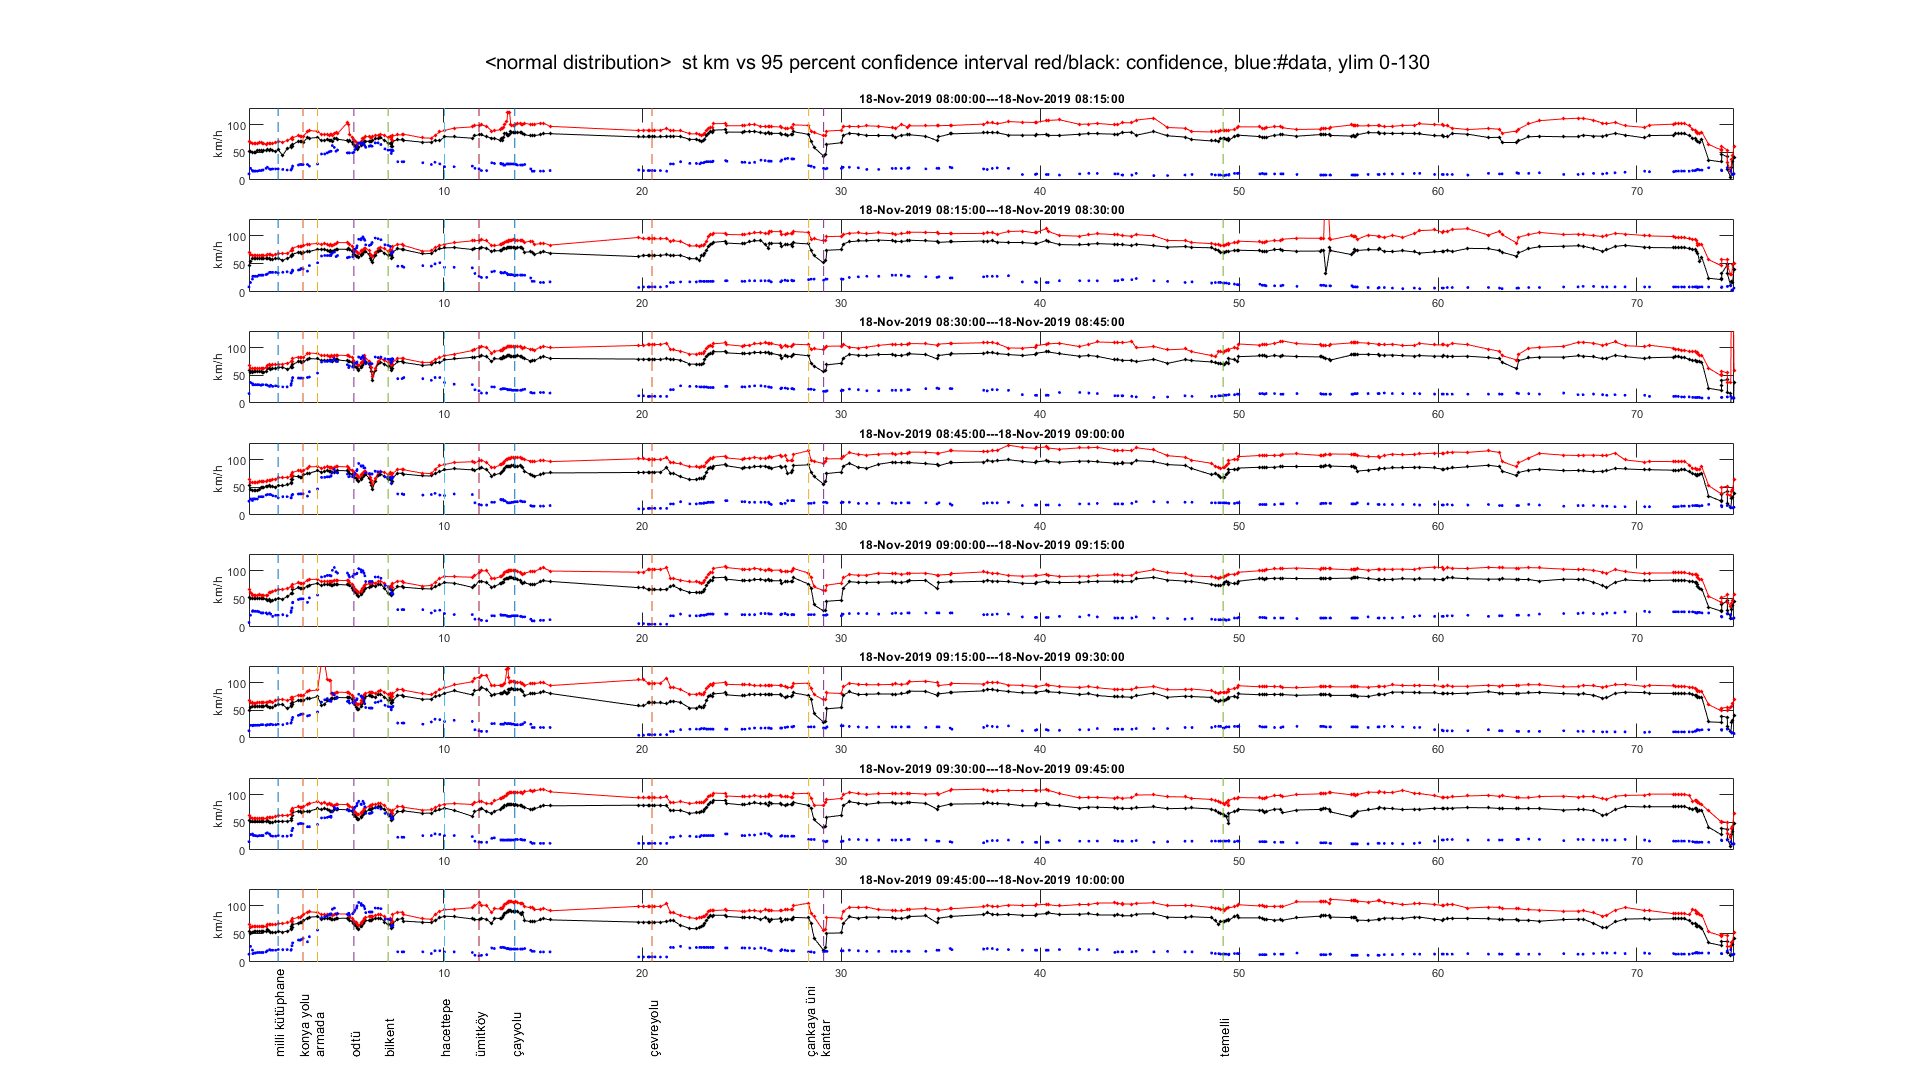

dir_chosen = 1;
[~,b] = ismember(aux_segments,segments.segment_id);
h=figure();
for i=1:1:length(aux_time)-1
    ax1 = subplot(length(aux_time)-1,1,i);
    plot(ax1,1e-3*segments.distance_from_start(b),con_min(:,i),'-*k',"MarkerSize",2);
    hold(ax1,'on');
    plot(ax1,1e-3*segments.distance_from_start(b),con_max(:,i),'-*r',"MarkerSize",2);
    hold(ax1,'on');
    scatter(ax1,1e-3*segments.distance_from_start(b),n_data(:,i),5,'blue','filled','MarkerEdgeAlpha',1,"MarkerFaceAlpha",1);
    xlim(ax1,1e-3*[min(segments.distance_from_start(b)) max(segments.distance_from_start(b))])
    ylabel('km/h')
    ylim([0 130]);
    yLimits = get(ax1,'YLim');
    title([datestr(aux_time(i)), '---', datestr(aux_time(i+1))])
    line(ax1,1e-3*[markers.distance_from_start(markers.dir == dir_chosen),markers.distance_from_start(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
end
text(ax1, 1e-3*double(markers.distance_from_start(markers.dir == dir_chosen)), -1.3*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
set(h,'Units','normalized','Position',[0 0 1 1]);
sgtitle('<normal distribution>  st km vs 95 percent confidence interval red/black: confidence, blue:#data, ylim 0-130')

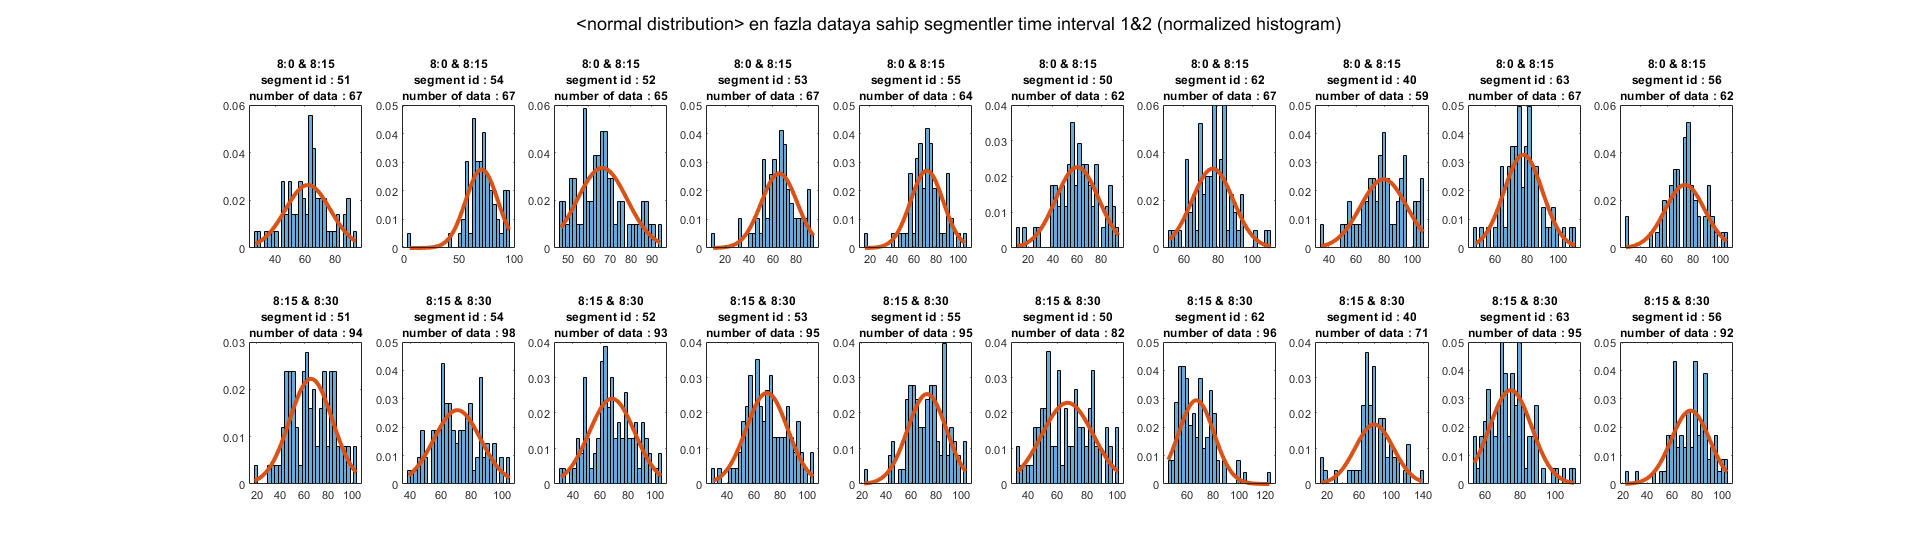

% sum
n_data(:,9) = sum(n_data,2);
% sort and get index
[~,idx] = sort(n_data(:,9),'descend');

% minimum data is in first time interval
t_j=[1,2]; % time interval
selected_list = idx(1:10); % first 10

h=figure();
for t=1:1:length(t_j)
    for i=1:1:length(selected_list)
        ax1 = subplot(length(t_j),length(selected_list),i + (t-1)*length(selected_list));
        x = min(pd_cell{selected_list(i),t_j(t)}.InputData.data):1:max(pd_cell{selected_list(i),t_j(t)}.InputData.data);
        histogram(ax1,pd_cell{selected_list(i),t_j(t)}.InputData.data,30,"Normalization","pdf")
        hold(ax1,'on');
        plot(ax1,x, pdf(pd_cell{selected_list(i),t_j(t)},x),"LineWidth",3)
        title({[num2str(aux_time(t_j(t)).Hour) ,':', num2str(aux_time(t_j(t)).Minute),' & ',num2str(aux_time(t_j(t)+1).Hour) ,':', num2str(aux_time(t_j(t)+1).Minute)], ...
            ['segment id : ', num2str(selected_list(i))], ...
            ['number of data : ', num2str(n_data(selected_list(i),t_j(t)))]})
    end
end
sgtitle('<normal distribution> en fazla dataya sahip segmentler time interval 1&2 (normalized histogram)')
set(h,'Units','normalized','Position',[0 0 1 0.5]);

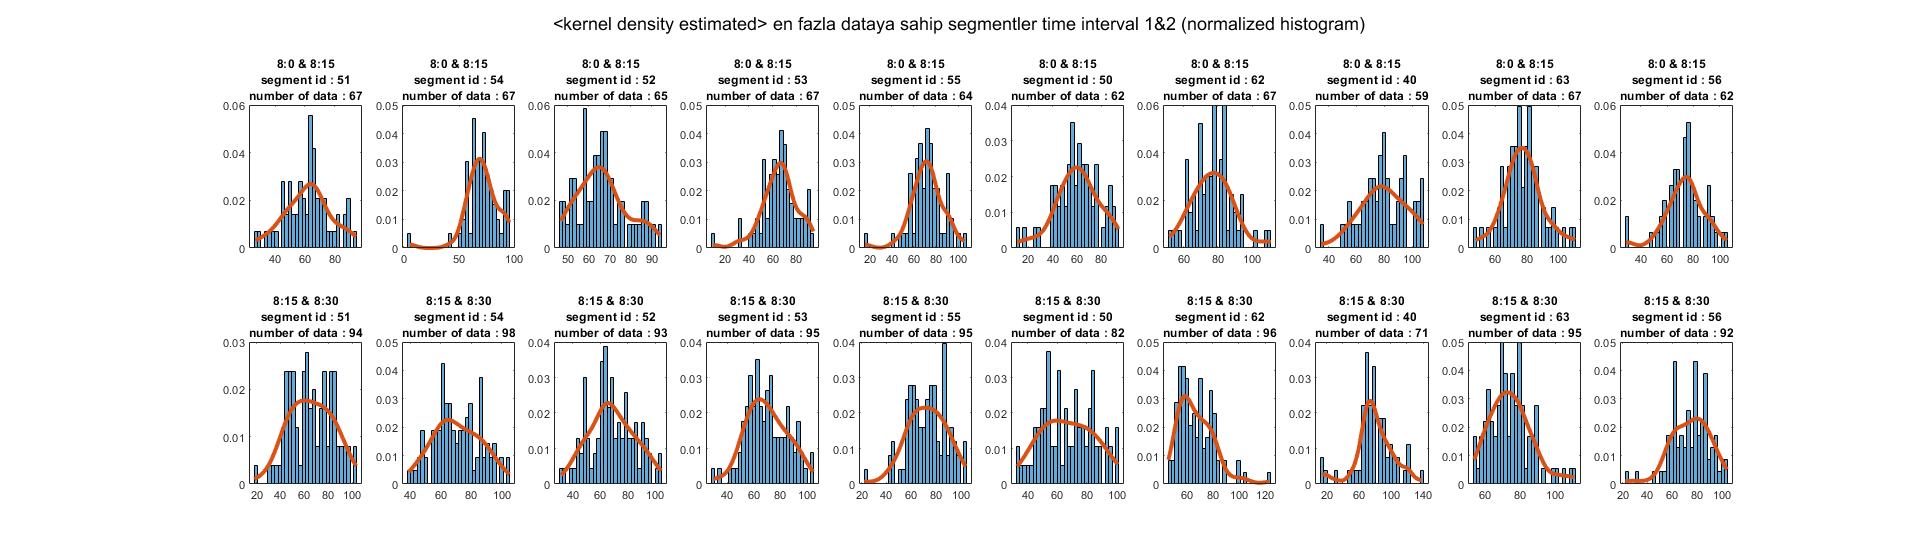

% sum
n_data(:,9) = sum(n_data,2);
% sort and get index
[~,idx] = sort(n_data(:,9),'descend');

% minimum data is in first time interval
t_j=[1,2]; % time interval
selected_list = idx(1:10); % first 10

h=figure();
for t=1:1:length(t_j)
    for i=1:1:length(selected_list)
        ax1 = subplot(length(t_j),length(selected_list),i + (t-1)*length(selected_list));
        x = min(kernel_cell{selected_list(i),t_j(t)}.InputData.data):1:max(kernel_cell{selected_list(i),t_j(t)}.InputData.data);
        histogram(ax1,kernel_cell{selected_list(i),t_j(t)}.InputData.data,30,"Normalization","pdf")
        hold(ax1,'on');
        plot(ax1,x, pdf(kernel_cell{selected_list(i),t_j(t)},x),"LineWidth",3)
        title({[num2str(aux_time(t_j(t)).Hour) ,':', num2str(aux_time(t_j(t)).Minute),' & ',num2str(aux_time(t_j(t)+1).Hour) ,':', num2str(aux_time(t_j(t)+1).Minute)], ...
            ['segment id : ', num2str(selected_list(i))], ...
            ['number of data : ', num2str(n_data(selected_list(i),t_j(t)))]})
    end
end
sgtitle('<kernel density estimated> en fazla dataya sahip segmentler time interval 1&2 (normalized histogram)')
set(h,'Units','normalized','Position',[0 0 1 0.5]);

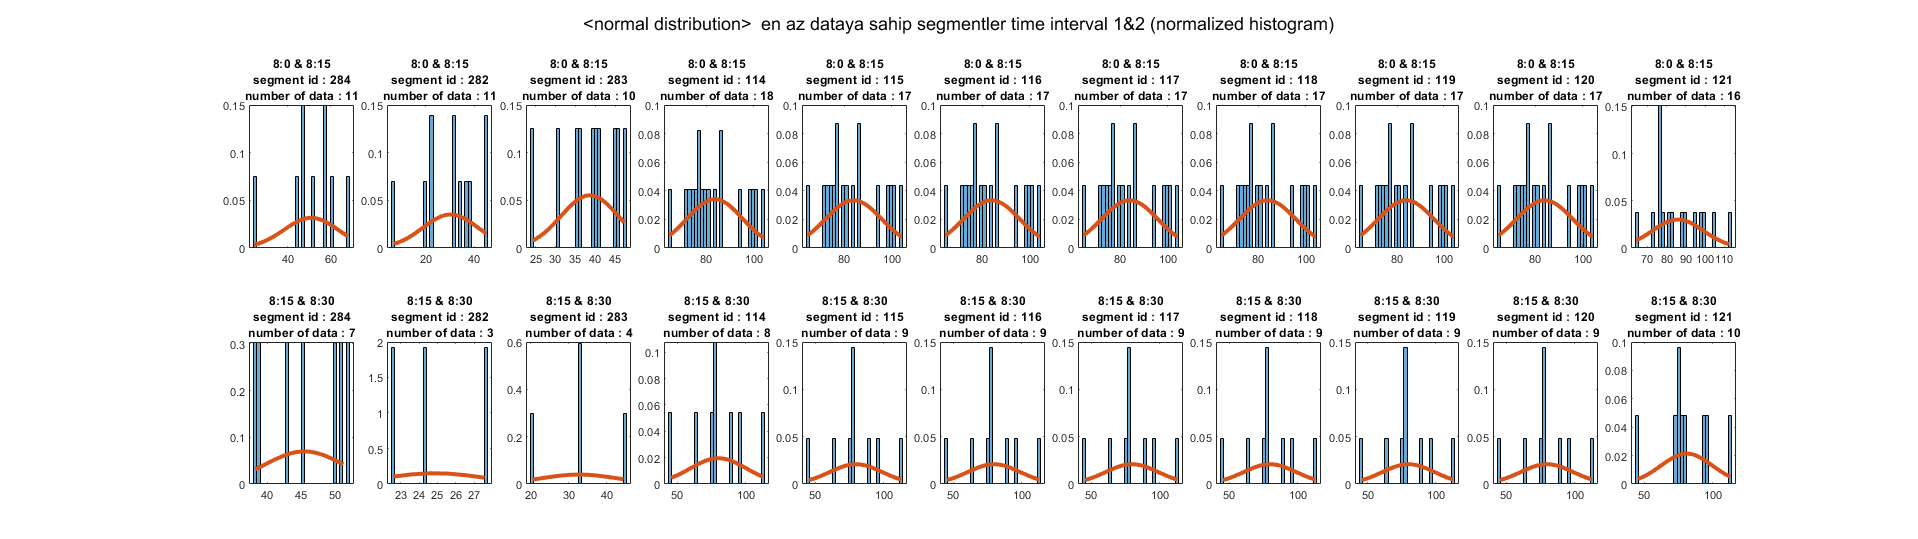

% sum
% n_data(:,9) = sum(n_data,2);
% sort and get index
% [~,idx] = sort(n_data(:,9),'descend');

% minimum data is in first time interval
t_j=[1,2]; % time interval
selected_list = idx(end-10:end); % last 10

h=figure();
for t=1:1:length(t_j)
    for i=1:1:length(selected_list)
        ax1 = subplot(length(t_j),length(selected_list),i + (t-1)*length(selected_list));
        x = min(pd_cell{selected_list(i),t_j(t)}.InputData.data):1:max(pd_cell{selected_list(i),t_j(t)}.InputData.data);
        histogram(ax1,pd_cell{selected_list(i),t_j(t)}.InputData.data,30,"Normalization","pdf")
        hold(ax1,'on');
        plot(ax1,x, pdf(pd_cell{selected_list(i),t_j(t)},x),"LineWidth",3)
        title({[num2str(aux_time(t_j(t)).Hour) ,':', num2str(aux_time(t_j(t)).Minute),' & ',num2str(aux_time(t_j(t)+1).Hour) ,':', num2str(aux_time(t_j(t)+1).Minute)], ...
            ['segment id : ', num2str(selected_list(i))], ...
            ['number of data : ', num2str(n_data(selected_list(i),t_j(t)))]})
    end
end
sgtitle('<normal distribution>  en az dataya sahip segmentler time interval 1&2 (normalized histogram)')
set(h,'Units','normalized','Position',[0 0 1 0.5]);

% sum
% n_data(:,9) = sum(n_data,2);
% sort and get index
% [~,idx] = sort(n_data(:,9),'descend');

% minimum data is in first time interval
t_j=[1,2]; % time interval
selected_list = idx(end-10:end); % last 10

h=figure();
for t=1:1:length(t_j)
    for i=1:1:length(selected_list)
        ax1 = subplot(length(t_j),length(selected_list),i + (t-1)*length(selected_list));
        x = min(kernel_cell{selected_list(i),t_j(t)}.InputData.data):1:max(kernel_cell{selected_list(i),t_j(t)}.InputData.data);
        histogram(ax1,kernel_cell{selected_list(i),t_j(t)}.InputData.data,30,"Normalization","pdf")
        hold(ax1,'on');
        plot(ax1,x, pdf(kernel_cell{selected_list(i),t_j(t)},x),"LineWidth",3)
        title({[num2str(aux_time(t_j(t)).Hour) ,':', num2str(aux_time(t_j(t)).Minute),' & ',num2str(aux_time(t_j(t)+1).Hour) ,':', num2str(aux_time(t_j(t)+1).Minute)], ...
            ['segment id : ', num2str(selected_list(i))], ...
            ['number of data : ', num2str(n_data(selected_list(i),t_j(t)))]})
    end
end
sgtitle('<kernel density estimated> en az dataya sahip segmentler time interval 1&2 (normalized histogram)')
set(h,'Units','normalized','Position',[0 0 1 0.5]);

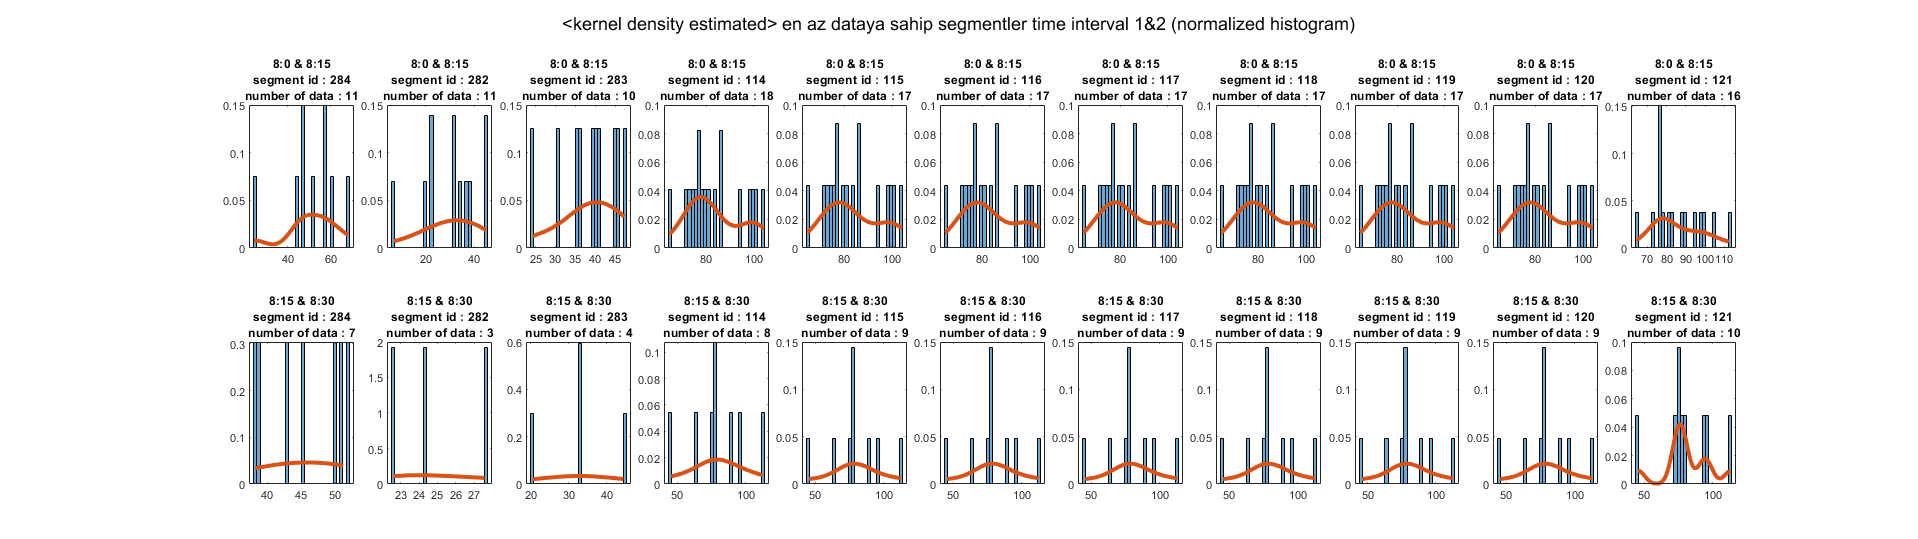

figure();
selected_segment_id = 300;

data = aug_data(aug_data.segment_id == selected_segment_id,:);
data = data(~isnan(data.speed),:); %nan'ları sil
data = sortrows(data,"time"); % time'a göre sort
histogram(data.speed,50)
title('speed histogram of selected segment')
ylabel('count')
xlabel('speed km/h')

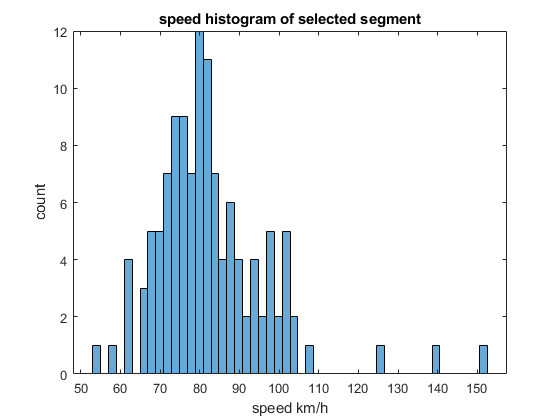

figure();
pd = fitdist(data.speed,'Kernel')%,"BandWidth")%,6)
plot(50:150,pdf(pd,50:150),'Color','b','LineWidth',2);

hold on
histogram(data.speed,50,"Normalization","pdf")
% hold on

pd =   KernelDistribution

    Kernel = normal
    Bandwidth = 4.10469
    Support = unbounded


% histogram(data.speed,50)

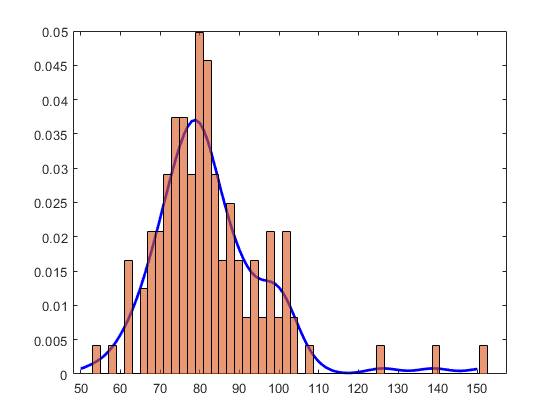

x = min(data.speed)-10:max(data.speed)+10;
y = cdf(pd,x);

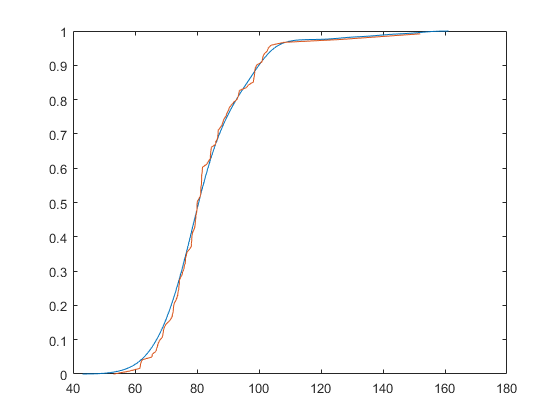

figure();
plot(x,y)
hold on
plot(sort(data.speed),(0:1:(length(data.speed)-1)) / length(data.speed)) 